syms y(t) m g b
eqn = m*diff(y,t) == m*g - b*y(t)^2;
cond = [y(0)==53];
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = \frac{\sqrt{g}\,\sqrt{m}\,\tanh\left(\frac{\sqrt{m}\,\mathrm{atanh}\left(\frac{53\,\sqrt{b}}{\sqrt{g}\,\sqrt{m}}\right)+\sqrt{b}\,\sqrt{g}\,t}{\sqrt{m}}\right)}{\sqrt{b}}$$

m = 100;
b = 53;
g = 10;
y = []


y =

     []



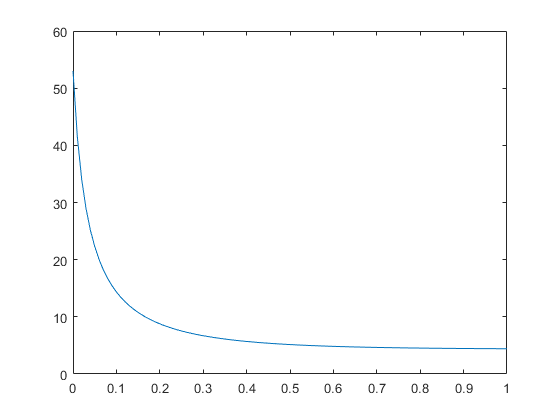

for t = 0:.01:1
    eval = subs(ySol);
    y(end+1) = eval;
end
t = 0:.01:1;
plot(t,y)

% also works with warning
% eval = subs(ySol);
% ezplot(eval,[0,2]);